syms a b c alpha beta
eqns = [sqrt(a^2+b^2+1)*cos(alpha)==1, sqrt(a^2+b^2)*cos(beta)+a==0, c==-120];
vars = [a,b,c];
[a,b,c] = solve(eqns, vars);
a = a(2,1)

$$a = -\frac{\cos\left(\beta \right)\,\sqrt{-\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)}}{\cos\left(\alpha \right)}$$

b = b(1,1)

$$b = \frac{\sqrt{\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)\,\left(\cos\left(\beta \right)-1\right)\,\left(\cos\left(\beta \right)+1\right)}}{\cos\left(\alpha \right)}$$

c = c(1,1)

$$c = -120$$

syms x_1 y_1 z_1 x_0 theta
eqns = [a*x_1+b*y_1-z_1+c==0, x_1==x_0, tan(theta/2)==y_1/z_1];
vars = [x_1,y_1,z_1];
[x_1,y_1,z_1] = solve(eqns, vars)

$$x\_1 = x_{0}$$

$$y\_1 = -\frac{\tan\left(\frac{\theta }{2}\right)\,\left(120\,\cos\left(\alpha \right)+x_{0}\,\cos\left(\beta \right)\,\sqrt{-\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)}\right)}{\cos\left(\alpha \right)-\tan\left(\frac{\theta }{2}\right)\,\sqrt{\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)\,\left(\cos\left(\beta \right)-1\right)\,\left(\cos\left(\beta \right)+1\right)}}$$

$$z\_1 = -\frac{120\,\cos\left(\alpha \right)+x_{0}\,\cos\left(\beta \right)\,\sqrt{-\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)}}{\cos\left(\alpha \right)-\tan\left(\frac{\theta }{2}\right)\,\sqrt{\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)\,\left(\cos\left(\beta \right)-1\right)\,\left(\cos\left(\beta \right)+1\right)}}$$

syms x_2 y_2 z_2 x_0 
eqns = [a*x_2+b*y_2-z_2+c==0, x_2==x_0, tan(theta/2)==-y_2/z_2];
vars = [x_2,y_2,z_2];
[x_2,y_2,z_2] = solve(eqns, vars)

$$x\_2 = x_{0}$$

$$y\_2 = \frac{\tan\left(\frac{\theta }{2}\right)\,\left(120\,\cos\left(\alpha \right)+x_{0}\,\cos\left(\beta \right)\,\sqrt{-\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)}\right)}{\cos\left(\alpha \right)+\tan\left(\frac{\theta }{2}\right)\,\sqrt{\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)\,\left(\cos\left(\beta \right)-1\right)\,\left(\cos\left(\beta \right)+1\right)}}$$

$$z\_2 = -\frac{120\,\cos\left(\alpha \right)+x_{0}\,\cos\left(\beta \right)\,\sqrt{-\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)}}{\cos\left(\alpha \right)+\tan\left(\frac{\theta }{2}\right)\,\sqrt{\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)\,\left(\cos\left(\beta \right)-1\right)\,\left(\cos\left(\beta \right)+1\right)}}$$

dis = sqrt((x_1-x_2)^2+(y_1-y_2)^2+(z_1-z_2)^2)

$$dis = \begin{array}{l} \sqrt{{\left(\frac{\tan\left(\frac{\theta }{2}\right)\,\sigma_{1}}{\cos\left(\alpha \right)+\sigma_{2}}+\frac{\tan\left(\frac{\theta }{2}\right)\,\sigma_{1}}{\cos\left(\alpha \right)-\sigma_{2}}\right)}^{2}+{\left(\frac{\sigma_{1}}{\cos\left(\alpha \right)+\sigma_{2}}-\frac{\sigma_{1}}{\cos\left(\alpha \right)-\sigma_{2}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=120\,\cos\left(\alpha \right)+x_{0}\,\cos\left(\beta \right)\,\sqrt{-\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)}\\ \sigma_{2}=\tan\left(\frac{\theta }{2}\right)\,\sqrt{\left(\cos\left(\alpha \right)-1\right)\,\left(\cos\left(\alpha \right)+1\right)\,\left(\cos\left(\beta \right)-1\right)\,\left(\cos\left(\beta \right)+1\right)} \end{array}$$

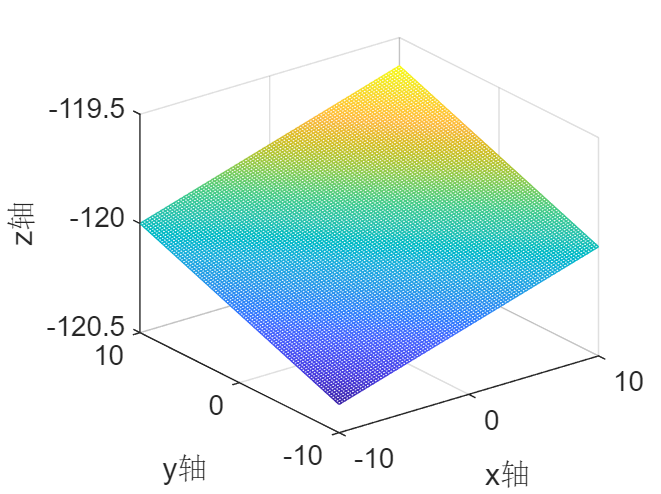

x0=0.9*1852;
beta=135;
beta=beta.*pi/180;
alpha=1.5.*pi/180;
theta=120.*pi/180;
[x0,beta]=meshgrid(x0,beta);
a=sqrt((cos(beta).*cos(beta))/(cos(alpha).*cos(alpha))-cos(beta).*cos(beta));
b=sqrt((1-cos(beta).*cos(beta)).*(1-cos(alpha).*cos(alpha))./(cos(alpha).*cos(alpha)));
c=-120;

[x,y] = meshgrid(-10:0.2:10);
z = a.*x + b.*y + c;
mesh(x,y,z)
xlabel('x轴'); ylabel('y轴'); zlabel('z轴'); % 加上坐标轴的标签

y1=(a*x0+c)./(1./tan(theta./2)-b);
y2=-(a*x0+c)./(1/tan(theta/2)+b);
z1=(a*x0+c)./(1-b*tan(theta/2));
z2=(a*x0+c)./(1+b*tan(theta/2));
d=sqrt((y1-y2).*(y1-y2)+(z1-z2).*(z1-z2));